## Load Training Data

[XTrain,TTrain] = digitTrain4DArrayData;

dsXTrain = arrayDatastore(XTrain,IterationDimension=4);
dsTTrain = arrayDatastore(TTrain);

dsTrain = combine(dsXTrain,dsTTrain);

Determine the number of classes in the training data.

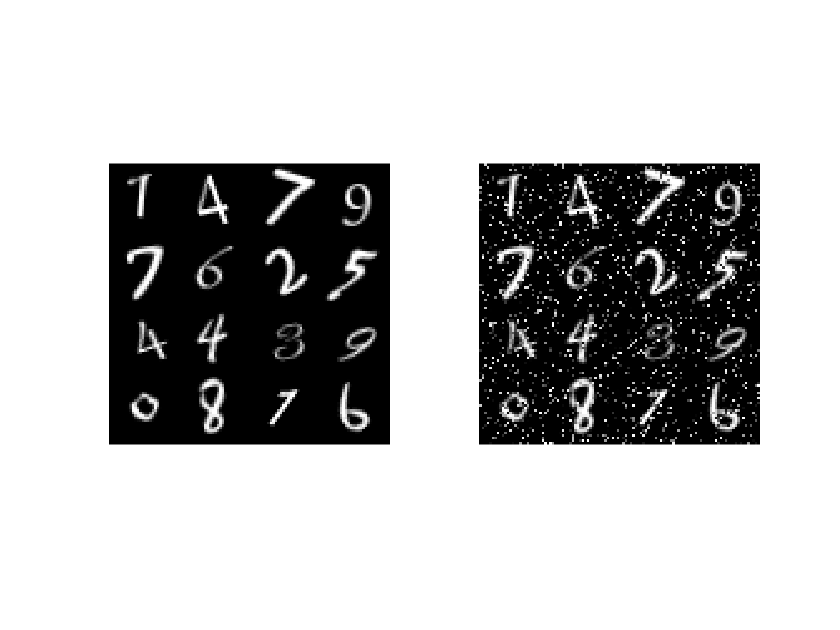

classes = categories(TTrain);
numClasses = numel(classes);
numImages = size(XTrain,4);
randompick = randperm(numImages,16);
XOriginal = XTrain(:,:,:,randompick);
noiseProp = 0.1;
noise = rand(size(XOriginal));
idx = rand(size(XOriginal)) < noiseProp;

XNoisy = XOriginal;
XNoisy(idx) = noise(idx);
I1 = imtile(XOriginal);
I2 = imtile(XNoisy);

figure;
subplot(1,2,1)
imshow(I1)
subplot(1,2,2)
imshow(I2)

## Define Network

imageInputSize = size(XTrain, 1:3)

imageInputSize =     28    28     1


layers = [
    imageInputLayer(imageInputSize,Mean=mean(XTrain,4))
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,20,Padding=1)
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,20,Padding=1)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer];
lgraph = layerGraph(layers);

dlnet = dlnetwork(lgraph);

## Specify Training Options

numEpochs = 15;
miniBatchSize = 32;
learningRate = 0.01;
momentum = 0.9;
jacobianRegularizationCoefficient = 1;

## Train Model

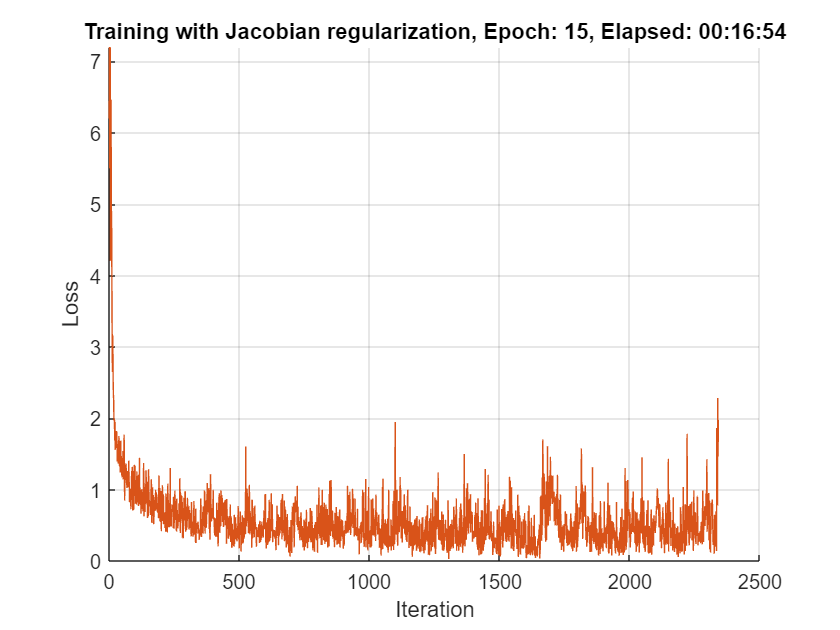

mbq = minibatchqueue(dsTrain,...
    MiniBatchSize=miniBatchSize,...
    MiniBatchFcn=@preprocessMiniBatch,...
    PartialMiniBatch="discard",...
    MiniBatchFormat=["SSCB",""]);
figure;
lineLossTrain = animatedline(Color=[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on
velocity = [];
iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Reset and shuffle mini-batch queue.
    shuffle(mbq);
    
    while hasdata(mbq)
        iteration = iteration + 1;
        
        % Read mini-batch of data.
        [X, T] = next(mbq);
     
        % Evaluate the model loss, gradients and the network state using
        % dlfeval and the modelLoss function listed at the end of the example.
        [totalLoss, gradTotalLoss, state] = dlfeval(@modelLoss, dlnet, X, T, ...
            miniBatchSize, jacobianRegularizationCoefficient);
        dlnet.State = state;
        
        % Update the network parameters.
        [dlnet, velocity] = sgdmupdate(dlnet,gradTotalLoss,velocity,learningRate,momentum);
        
        % Plot the training progress.
        D = duration(0,0,toc(start),Format="hh:mm:ss");
        addpoints(lineLossTrain,iteration,double(totalLoss))
        title("Training with Jacobian regularization" + ", Epoch: " + epoch + ", Elapsed: " + string(D))
        drawnow
        
    end
end

## Load Reference Network

dlnetReference = load("dlnetWithoutJacobian.mat").dlnetReference;

Error using load
'dlnetWithoutJacobian.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Hp\OneDrive\Documents\MATLAB\Examples\R2023a\nnet\TrainDeepLearningNetworkWithJacobianRegularizationExample

Change the MATLAB current folder or add its folder to the MATLAB path.

## Test Model.

[XTest, TTest] = digitTest4DArrayData;
classes = categories(TTest);
% Initialize test parameters and arrays.
noiseProps = 0:0.05:0.5;

% Prepare arguments for mini-batch queue.
dsTTest = arrayDatastore(TTest);
miniBatchSize = 5000;
        
for i = 1:numel(noiseProps)
    % Load the noise proportion.
    noiseProp = noiseProps(i);
    fprintf("Testing robustness to noise proportion %1.2g\n", noiseProp)
    
    % Set a proportion of the pixels to a random grayscale value.         
    noise = rand(size(XTest));
    idx = rand(size(XTest)) < noiseProp;
    XNoisy = XTest;
    XNoisy(idx) = noise(idx);
    
    % Prepare mini-batch queue with noisy test data.
    dsXTest = arrayDatastore(XNoisy,IterationDimension=4);
    dsTest = combine(dsXTest,dsTTest);
    mbq = minibatchqueue(dsTest,...
        MiniBatchSize=miniBatchSize,...
        MiniBatchFcn=@preprocessMiniBatch,...
        MiniBatchFormat=["SSCB",""]);
        
    % Loop over batches to find predicted classifications.
    while hasdata(mbq)
        [XNoisy, T] = next(mbq);
        
        % Classify noisy data with the robust network.
        YPredNoisy = predict(dlnet, XNoisy);
        
        % Convert the predictions into labels.
        YPred = onehotdecode(YPredNoisy, classes, 1)';
        TTestBatch = onehotdecode(T, classes, 1)';
        
        % Evaluate accuracy of predictions.
        accuracyRobust(i) =  mean(YPred == TTestBatch);
        
        % Classify noisy data with reference network.
        YPredNoisy = predict(dlnetReference, XNoisy);
        
        % Convert the predictions into labels.
        YPred = onehotdecode(YPredNoisy, classes, 1)';
        
        % Evaluate accuracy of predictions.
        accuracyReference(i) =  mean(YPred == TTestBatch);
    end

end
x = noiseProps';

figure;

plot(x,accuracyRobust*100, "-o", x, accuracyReference*100, "-o")
xlabel("Proportion of noise")
ylabel("Accuracy (%)")
xlim([0,0.5]);
ylim([0,100]);
title("Image classification accuracy")
legend("Jacobian regularization", "Reference");

## Test Specific Example 

% Choose test image
testchoice = 1;

% Add noise, with a proportion of 0.15, to the first image.
noise = rand(size(XTest(:,:,:,testchoice)));
idx = rand(size(XTest(:,:,:,testchoice))) < 0.15;
XNoisy = XTest(:,:,:,testchoice);
XNoisy(idx) = noise(idx);

% Convert to dlarray.
XTest  = dlarray(XTest(:,:,:,testchoice),"SSCB");
XNoisy = dlarray(XNoisy,"SSCB");

% Print true number classification
disp("True digit label: " + char(TTest(testchoice)));
YPredTestJR = predict(dlnet, XTest);
YPredTestJR = onehotdecode(YPredTestJR, classes, 1)';
disp("Robust network classification of original image: " + char(YPredTestJR));
YPredNoisyJR = predict(dlnet, XNoisy);
YPredNoisyJR = onehotdecode(YPredNoisyJR, classes, 1)';
disp("Robust network classification of noisy image: " + char(YPredNoisyJR));
YPredTest = predict(dlnetReference, XTest);
YPredTestR = onehotdecode(YPredTest, classes, 1)';
disp("Reference network classification of original image: " + char(YPredTestR));
YPredNoisy = predict(dlnetReference, XNoisy);
YPredNoisyR = onehotdecode(YPredNoisy, classes, 1)';
disp("Reference network classification of noisy image: " + char(YPredNoisyR));
figure;
I1 = extractdata(XTest(:,:,:,testchoice));
subplot(1,2,1)
imshow(I1)
title("Original image")
xlabel({"Prediction without"; "Jacobian regularization: " + char(YPredTestR);...
    "Prediction with"; "Jacobian regularization: " + char(YPredTestJR)})
I2 = extractdata(XNoisy);
subplot(1,2,2)
imshow(I2)
title("Noisy image")
xlabel({"Prediction without"; "Jacobian regularization: " + char(YPredNoisyR);...
    "Prediction with"; "Jacobian regularization: " + char(YPredNoisyJR)})

function [totalLoss, gradTotalLoss, state] = modelLoss(net, X, T, miniBatchSize, jacobianRegularizationCoefficient)

% Find prediction and loss.
[Z,state] = forward(net, X);
loss = crossentropy(Z, T);

numClasses = size(Z,1);
numProjections = 1;
regularizationTerm = 0;

% Compute Jacobian term and its gradient.
for i = 1:numProjections
   
    % Sample a matrix whose elements are drawn from the standard Normal distribution.
    rndarray = randn(numClasses, miniBatchSize);
    
    % Normalize the columns of the random matrix.
    rndarray = normc(rndarray);
    
    % Compute the vector-vector product.
    vectorproduct = rndarray(:)' * Z(:);  
   
    % Compute the gradient of the vector-vector product. Since another
    % derivative will be taken, set EnableHigherDerivatives to true.
    vectorJacobianTerm = dlgradient(vectorproduct, X, EnableHigherDerivatives=true);
    
    % Multiply by necessary constants to obtain approximation of the
    % Frobenius norm of the Jacobian.
    regularizationTerm = regularizationTerm + numClasses*sum(vectorJacobianTerm.^2,"all") /(numProjections*miniBatchSize);
end
totalLoss = loss + jacobianRegularizationCoefficient/2 * regularizationTerm;

% Calculate the gradient of the loss.
gradTotalLoss = dlgradient(totalLoss, net.Learnables);
end

function [X, T] = preprocessMiniBatch(XCell,TCell)
    % Extract image data from cell and concatenate
    X = cat(4,XCell{1:end});

    % Extract label data from cell and concatenate
    T = cat(2,TCell{1:end});
    
    % One-hot encode labels
    T = onehotencode(T,1);
end